## Sensitivity analysis of a defected beam using DpROM

**DESCRIPTION**:                                                      

With this script we study first and second order approximations of HB coefficients of a parametric fe model of a nonlinear defected beam presented in [1] following the HB-sensitivity approach described in [2].

The Defect-parametric Reduced Order Model (DpROM) is constructed using a reduction basis V containing Vibration Modes (VM), Modal Derivatives (MD) and Defect Sensitivities (DS, i.e. VM derivatives wrt defect amplitudes). Again, refer to [1] for further details.

While running the nominal HB solution (using DpROM @p0), sensitivity  analysis to parameters p (defect amplitudes) is also performed. First- and second-order approximations of the HB coefficients are thus obtained from the nominal solution by applying a Taylor expansion in the reduced space.

Once nominal solution @p0 and sensitivities are available, we compute

- first order approximation @p0+dp

- second order approximation @p0+dp

- DpROM solution @p0+dp

- ROM solution @p0+dp (non-parametric ROM, basis with VM and MD)

being dp a variation wrt the nominal parameter vector p0. The reduced solution is eventually expanded back to the full order space.

Nominal solution, first and second order approximated solution, and re-simulated solutions are plotted to show the accuracy of approximation.

**REFERENCES**:

[1] Marconi, Tiso, Quadrelli, Braghin, *A higher-order parametric nonlinear reduced-order model for imperfect structures using Neumann expansion*', Nonlinear Dynamics 104(4), [http://doi.org/10.1007/s11071-021-06496-y](http://doi.org/10.1007/s11071-021-06496-y)

[2] A. Saccani, J. Marconi & P. Tiso. *Sensitivity Analysis of Nonlinear Frequency Response of Defected Structures*, Nonlinear Dynamics. PREPRINT (Version 1) available at Research Square [https://doi.org/10.21203/rs.3.rs-1707949/v1](https://doi.org/10.21203/rs.3.rs-1707949/v1)

Author: Alexander Saccani, Msc in mechanical engineering, Politecnico di Milano

Created:  09/2021

% Initialize Matlab
clear
close all
clc
format shortg

## SETTINGS

% if USEJULIA == 1, tensors are computed with Julia, otherwise with Matlab.
% If you set USEJULIA to 1 make sure you have Julia and Mex.jl installed
% (see https://github.com/byuflowlab/Mex.jl). 
% See also "../papers/DpROM/References.pdf"
USEJULIA = 0;

% Sensitivity Analysis settings ___________________________________________
SENS = 0;	% perform sensitivity analysis (1) or used stored results (0).
filename_sens = 'sens_2VM_H3';	% file with sens analysis results stored
method_sens = 'normal';         % available options are 'normal'/'omegaconst'

% number of vibration modes used in modal reduction (MAKE SURE it's the
% same as in the loaded data, if loading sensitivities - see above)
n_VMs = 2;

% do you want to save sensitivity analysis results?
save_sens = 0;
save_as = 'sens_2VM_H3.mat';	% name of the file you save results

% DpROM settings __________________________________________________________
% parametric formulation for defects
FORMULATION = 'N1'; % N1/N1t/N0
VOLUME = 1;         % integration over defected (1) or nominal volume (0)

% defect amplitudes
xi1 = 0.3;    % defect amplitude - arch
xi2 = 0.1;	  % defect amplitude - shifted arch
xi3 = 0.1;    % defect amplitude - wall angle
xi4 = 0.05;   % defect amplitude - thinning beam

% Common settings for HB __________________________________________________
imod = 1;           % eigenfreq to study
H = 3;             	% harmonic order
startfactor = 1.2;  % start frequency = f0(imod) * startfactor
endfactor = 0.8;    %   end frequency = f0(imod) * endfactor
ds = 20;           	% Path continuation step size
exc_lev = 2000;     % excitation level

## Prepare Model (full nominal, full defected)

% DATA ____________________________________________________________________
E       = 70e9;     % Young's modulus [Pa]
rho     = 2800;     % density [kg/m^3]
nu      = 0.30;     % Poisson's ratio 
thickness = .2;     % [m] beam's out-of-plane thickness

% Material
myMaterial = KirchoffMaterial();
set(myMaterial,'YOUNGS_MODULUS',E,'DENSITY',rho,'POISSONS_RATIO',nu);
myMaterial.PLANE_STRESS = false;	% set "true" for plane_stress
% Element
myElementConstructor = @()Quad8Element(thickness, myMaterial);

% MESH_____________________________________________________________________
Lx = 2;
Ly = .050;
nx = 40;
ny = 2;
[nodes, elements, nset] = mesh_2Drectangle(Lx, Ly, nx, ny, 'QUAD8');

 Meshing 80 elements (QUAD8) ...  0.00 s
  Nodes: 325 
  Dofs:  650 



% nominal mesh
MeshNominal = Mesh(nodes);
MeshNominal.create_elements_table(elements,myElementConstructor);
MeshNominal.set_essential_boundary_condition([nset{1} nset{3}],1:2,0)

#### Create defect-shapes

% (1) arch defect
vd1 = Ly * sin(pi/Lx * nodes(:,1));	% y-displacement 
arc_defect = zeros(numel(nodes),1);
arc_defect(2:2:end) = vd1;        	% vectorized defect-field

% (2) shifted arch defect
vd2 = Ly * sin(pi/Lx * nodes(:,1) - pi/2);	% y-displacement 
sh_arc_defect = zeros(numel(nodes),1);         
sh_arc_defect(2:2:end) = vd2;             	% vectorized defect-field

% (3) wall angle
th = 5; % wall angle of 5°
ud = nodes(:,2) * tan(th*pi/180);
wallangle = zeros(numel(nodes),1);
wallangle(1:2:end) = ud;

% (4) thinning beam
nodes_translated = [nodes(:,1), nodes(:,2) - Ly/2];
shape_fun  = (2/Lx)^2 * (nodes_translated(:,1) - Lx/2).^2;
nodes_def_thin = [nodes_translated(:,1), ...
    nodes_translated(:,2).*shape_fun + Ly/2 ];
vd3 = nodes_def_thin(:,2) - nodes(:,2);
thinbeam = zeros(numel(nodes),1);
thinbeam(2:2:end) = vd3;

#### Create Defect-Base U

% defected mesh
U = [arc_defect, sh_arc_defect, wallangle, thinbeam]; % defect basis
xi = [xi1 xi2 xi3 xi4]'; % parameter vector
m = length(xi); % number of parameters

% update defected mesh nodes
d = U*xi; % displacement fields introduced by defects
dd = [d(1:2:end) d(2:2:end)]; 
nodes_defected = nodes + dd; % nominal + d ---> defected 
MeshDefected = Mesh(nodes_defected);
MeshDefected.create_elements_table(elements,myElementConstructor);
MeshDefected.set_essential_boundary_condition([nset{1} nset{3}],1:2,0)
    fprintf([' Arc defect:           %.2f * beam thickness \n' ...
        ' Shifted Arc defect:   %.2f * beam thickness \n' ...
        ' Wall angle:           %.2f° (xi = %.1f) \n' ...
        ' Thinning beam defect: %.1f * beam thickness \n'], ...
        xi1,xi2,th*xi3,xi3,xi4)

 Arc defect:           0.30 * beam thickness 
 Shifted Arc defect:   0.10 * beam thickness 
 Wall angle:           0.50° (xi = 0.1) 
 Thinning beam defect: 0.1 * beam thickness 


#### Plot defected shape

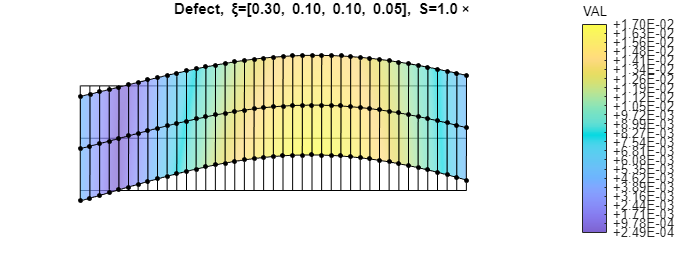

figure('units','normalized','position',[.2 .3 .6 .4])
elementPlot = elements(:,1:4); hold on % plot only corners (otherwise it's a mess)
PlotMesh(nodes_defected, elementPlot, 0); 
PlotMesh(nodes,elementPlot,0);
v1 = reshape(U*xi, 2, []).';
S = 1;%2 * Ly / max(abs(v1(:)));
hf=PlotFieldonDeformedMesh(nodes, elementPlot, v1, 'factor', S);
title(sprintf('Defect, \\xi=[%.2f, %.2f, %.2f, %.2f], S=%.1f\\times',...
    xi1, xi2, xi3, xi4, S))
axis normal; grid on; box on; set(hf{1},'FaceAlpha',.7); drawnow


% ASSEMBLY ________________________________________________________________
% nominal
NominalAssembly = Assembly(MeshNominal);
Mn = NominalAssembly.mass_matrix();
nNodes = size(nodes, 1);
u0 = zeros( MeshNominal.nDOFs, 1);
[Kn,~] = NominalAssembly.tangent_stiffness_and_force(u0);
    % store matrices
    NominalAssembly.DATA.K = Kn;
    NominalAssembly.DATA.M = Mn;

% defected
DefectedAssembly = Assembly(MeshDefected);
Md = DefectedAssembly.mass_matrix();
[Kd,~] = DefectedAssembly.tangent_stiffness_and_force(u0);
    % store matrices
    DefectedAssembly.DATA.K = Kd;
    DefectedAssembly.DATA.M = Md;

% External force __________________________________________________________
% forced dof is the vertical in midspan of beam
node_dofs = MeshNominal.get_DOF_from_location([Lx/2, Ly/2]);
forced_dof = node_dofs(2);
Fext = zeros(nNodes*2, 1);
Fext( forced_dof ) = 1;
Fextc = NominalAssembly.constrain_vector( Fext );

% Let us also define the index of the forced dof in the constrained vector:
forced_dof_c = NominalAssembly.free2constrained_index( forced_dof );

## Eigenmodes, number of vibration modes in ROM

% Eigenvalue problem_______________________________________________________
% Vibration Modes (VM): nominal
Knc = DefectedAssembly.constrain_matrix(Kn);
Mnc = DefectedAssembly.constrain_matrix(Mn);
[VMn,om] = eigs(Knc, Mnc, n_VMs, 'SM');
[f0n,ind] = sort(sqrt(diag(om))/2/pi);
VMn = VMn(:,ind);
for ii = 1:n_VMs
    VMn(:,ii) = VMn(:,ii)/max(sqrt(sum(VMn(:,ii).^2,2)));
end
VMn = NominalAssembly.unconstrain_vector(VMn);

% Vibration Modes (VM): defected
Kdc = DefectedAssembly.constrain_matrix(Kd);
Mdc = DefectedAssembly.constrain_matrix(Md);
[VMd,om] = eigs(Kdc, Mdc, n_VMs, 'SM');
[f0d,ind] = sort(sqrt(diag(om))/2/pi);
VMd = VMd(:,ind);
for ii = 1:n_VMs
    VMd(:,ii) = VMd(:,ii)/max(sqrt(sum(VMd(:,ii).^2,2)));
end
VMd = DefectedAssembly.unconstrain_vector(VMd);

% Damping _________________________________________________________________
alfa = 3.1;
beta = 6.3*1e-6;
D = alfa*Mn + beta*Kn; % Rayleigh damping
NominalAssembly.DATA.D = D;
Dc = NominalAssembly.constrain_matrix(D);

## Modal Derivatives & Defect Sensitivities

% nominal
[MDn, MDname] = modal_derivatives(NominalAssembly, elements, VMn);

 dKdq, assembling 80 elements ... 0.16 s
 dKdq, assembling 80 elements ... 0.17 s


% defected
MDd = modal_derivatives(DefectedAssembly, elements, VMd);

 dKdq, assembling 80 elements ... 0.16 s
 dKdq, assembling 80 elements ... 0.16 s



% defect sensitivities
[DS, names] = defect_sensitivities(NominalAssembly, elements, VMn, U, ...
    FORMULATION);

 dKdxi, assembling 80 elements ... 0.03 s
 dKdxi, assembling 80 elements ... 0.03 s
 dKdxi, assembling 80 elements ... 0.03 s
 dKdxi, assembling 80 elements ... 0.03 s
 


## Generate ROM tensors (ROM-n DpROM ROM-d)

define reduced order basis

Vn = [VMn MDn];     % reduced order basis (ROM-n)
V  = [VMn MDn DS]; 	% reduced order basis (DpROM)
Vd = [VMd MDd];   	% reduced order basis (ROM-d)

% orthonormalize reduction basis
Vn = orth(Vn);	% ROM-n
V  = orth(V);	% DpROM
Vd = orth(Vd);	% ROM-d

% standard reduced order model (no defects in the mesh)
tensors_ROMn = reduced_tensors_ROM(NominalAssembly, elements, Vn, USEJULIA);

 REDUCED TENSORS (standard ~ using Matlab):
 Assembling 80 elements ... 2.10 s (2.10 s)
 SPEED: 38.2 el/s
 SIZEs: 5 




% standard reduced order model (defects in the mesh)
tensors_ROMd = reduced_tensors_ROM(DefectedAssembly, elements, Vd, USEJULIA);

 REDUCED TENSORS (standard ~ using Matlab):
 Assembling 80 elements ... 2.14 s (2.14 s)
 SPEED: 37.5 el/s
 SIZEs: 5 



tensors_ROMd.xi = xi; % save for which xi ROMd is computed

% parametric formulation for defects
tensors_DpROM = reduced_tensors_DpROM(NominalAssembly, elements, ...
    V, U, FORMULATION, VOLUME, USEJULIA); %compute tensors

 REDUCED TENSORS (N1 ~ using Matlab):
 Assembling 80 elements ... 5.61 s (5.61 s)
 SPEED: 14.3 el/s
 SIZEs: 13 - 4 




% evaluate the defected tensors at xi
[Q2, ~, ~, ~, ~, Mxi] = DefectedTensors(tensors_DpROM, xi);

Mnr = Vn'*Mn*Vn; 	% reduced mass matrix (ROM-n)
Mdr = Vd'*Md*Vd; 	% reduced mass matrix (ROM-d)
if VOLUME == 0
    Mr  = V' *Mn*V; 	% reduced mass matrix (DpROM)
elseif VOLUME == 1
    Mr  = V' *Md*V; 	% reduced mass matrix (DpROM)
end

% compute eigenfrequencies of reduced models
f0_ROMn = sort(sqrt( eigs(tensors_ROMn.Q2, Mnr, n_VMs, 'SM') )/2/pi);
f0_ROMd = sort(sqrt( eigs(tensors_ROMd.Q2, Mdr, n_VMs, 'SM') )/2/pi); 
f0_DpROM = sort(sqrt( eigs(Q2, Mr, n_VMs, 'SM') )/2/pi);
f0_DpROM_Mxi = sort(sqrt( eigs(Q2, Mxi, n_VMs, 'SM') )/2/pi);

% disp eigenfrequencies in command window
disp(table(f0n, f0_ROMn, f0d, f0_ROMd, f0_DpROM, f0_DpROM_Mxi))

     f0n      f0_ROMn     f0d      f0_ROMd    f0_DpROM    f0_DpROM_Mxi
    ______    _______    ______    _______    ________    ____________
    67.223    67.223     69.536    69.536      69.419        69.417   
    184.23    184.23      179.7     179.7      179.92        179.92   


## Nominal solution + Sensitivity Analysis (HB)

% number of dof
n = size(Vn, 2);        % number of DOFs of ROMn
n_DpROM = size(V,2);    % number of DOFs of DpROM

if SENS == 1
        
    % PREPARE MODEL _______________________________________________________   
    % ROMn: reduced matrices (in the reduction base also DS are used)
    [Q2n, Q3n, Q4n, Q3tn, Q4tn] = DefectedTensors(tensors_DpROM, 0*xi);
    
    Knr = Q2n;          % reduced linear stiffness matrix
    Mnr = V' * Mn * V;	% reduced mass matrix
    Dnr = V' * D  * V;	% reduced damping matrix
    Fnr = V'*Fext;     	% reduced external force vector
    
    % create system for NlVib
    ROMn_Assembly = Assembly(MeshNominal, V);
    ROMn_Assembly.DATA.K = Knr;
    ROMn_Assembly.DATA.M = Mnr;
    ROMn_Assembly.DATA.D = Dnr;
    
    ROMn_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(Q3n,...
        Q4n, Q3tn, Q4tn, q); % nonlinear force

    ROMn_System = FE_system(ROMn_Assembly, Fnr, 'custom'); % create system
    
    ROMn_System.Fex1 = V' * Fext * exc_lev; % excitation force
    
    % ANALYSIS PARAMETERS _________________________________________________
    omi = 2*pi*f0n(imod);       % linear eigenfrequency
    N = 3*H+1;                  % number of time samples per period
    Om_s = omi * startfactor;	% start frequency
    Om_e = omi * endfactor;    	% end frequency

    % SENSITIVITY ANALYSIS PARAMETERS______________________________________
    % function handle for derivatives of forces in time domain
    derFunHandle = @(q) DpROM_derivatives(q, tensors_DpROM);
    
    % Ns: number of samples in AFT procedure
    Ns = 2*N;

    % defining sensitivity analysis post process. function
    funPostprocess = @(X) HB_sensitivity(X,ROMn_System, derFunHandle,...
        m, method_sens, 2, Ns);
    
    % COMPUTE FRs _________________________________________________________
    fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)

    % Initial guess (solution of underlying linear system)
    Q1 = (-Om_s^2*Mnr + 1i*Om_s*Dnr + Knr) \ ROMn_System.Fex1;
    y0 = zeros( (2*H+1)*n_DpROM , 1);
    y0( n_DpROM + (1:2*n_DpROM) ) = [real(Q1);-imag(Q1)];

    % stuff for scaling
    qscl = max(abs((-omi^2*Mnr + 1i*omi*Dnr + Knr) \ ROMn_System.Fex1));
    dscale = [y0*0+qscl; omi];
    Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1,...
        'dsmax',ds*2, 'stepmax', 1e4);
    
    % Solve and continue w.r.t. Om
    [Xn, Solinfo, Sol] = solve_and_continue(y0, ...
        @(X) HB_residual(X, ROMn_System, H, N, 'FRF'), ...
        Om_s, Om_e, ds, Sopt, funPostprocess);
    
    % Interpret solver output
    results.red.nominal = nlvib_decode(Xn, Solinfo, Sol, 'FRF', 'HB',...
        n_DpROM, H); %(reduced space, nominal solution)
    
    Sens = [Sol.Sens];
    
    % save results of sensitivity analysis + nominal solution
    if save_sens == 1
        save(save_as,'results','Sens','Xn','n','H','imod','exc_lev',...
        'method_sens','USEJULIA');
    end

else
    
    % load file with stored sensitivity analysis and nominal solution
    load(filename_sens)

end

## Defected solution with sensitivity

%get first and second order approximated solution for parameter variation
X12 = update_response(Xn, Sens, xi); % Xnominal + Sens + delta par. --> X12

% interpret solver output
% reduced space - lin. approx.
results.red.lin = nlvib_decode(X12.lin, 0, 0, 'FRF', ...
                        'HB', n_DpROM, H);

% reduced space - quad. approx.
results.red.quad = nlvib_decode(X12.quad, 0, 0, 'FRF',...
                        'HB', n_DpROM, H);

## Simulate DpROM to obtain defected solution

% PREPARE MODEL ___________________________________________________________

% evaluate the defected tensors at xi
[Q2, Q3, Q4, Q3t, Q4t] = DefectedTensors(tensors_DpROM, xi);

% reduced matrices
Kr = Q2;         	% reduced linear stiffness matrix
if VOLUME == 0
    Mr  = V'*Mn*V; 	% reduced mass matrix (DpROM), nominal volume
elseif VOLUME == 1
    Mr  = V'*Md*V; 	% reduced mass matrix (DpROM), defected volume
end
Dr = V' * D  * V; 	% reduced damping matrix
Fr = V'*Fext;    	% reduced external force vector

% Let us defined the DpROM Assembly (although the ReducedAssembly class is
% not strictly necessary, we want to define a different object - remember
% that the synthax obj1=obj2 does NOT copy an object)

%create system for NlVib
DpROM_Assembly = Assembly(MeshNominal, V); 
DpROM_Assembly.DATA.K = Kr;
DpROM_Assembly.DATA.M = Mr;
DpROM_Assembly.DATA.D = Dr;
DpROM_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(Q3,...
    Q4, Q3t, Q4t, q); %nonlinear force
DpROM_System = FE_system(DpROM_Assembly, Fr, 'custom'); %generate system
% define forcing
DpROM_System.Fex1 = V' * Fext * exc_lev;

% ANALYSIS PARAMETERS _____________________________________________________
omi = 2*pi*f0_DpROM(imod); 	% linear eigenfrequency           
Om_s = omi * startfactor;	% start frequency
Om_e = omi * endfactor;     % end frequency
N = 3*H +1;                 % number of samples for A.F.T.

% COMPUTE FRs _____________________________________________________________
fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)



 FRF from 523.41 to 348.94 rad/s 




% Initial guess (solution of underlying linear system)
Q1 = (-Om_s^2*Mr + 1i*Om_s*Dr + Kr) \ DpROM_System.Fex1;
y0 = zeros( (2*H+1)*n_DpROM , 1);
y0( n_DpROM + (1:2*n_DpROM) ) = [real(Q1);-imag(Q1)];

% stuff for scaling
qscl = max(abs((-omi^2*Mr + 1i*omi*Dr + Kr) \ DpROM_System.Fex1));
dscale = [y0*0+qscl; omi];
Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1,...
    'dsmax',ds*2, 'stepmax', 1e4,'reversaltolerance', 0.5);

% Solve and continue w.r.t. Om
[X, Solinfo, Sol] = solve_and_continue(y0, ...
    @(X) HB_residual(X, DpROM_System, H, N, 'FRF'), ...
    Om_s, Om_e, ds, Sopt);

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     2.23239e+07                      1.94e+13               1
     1          2       0.0760956    0.000154394       1.49e+09               1
     2          3     2.30801e-14    1.13533e-07            782               1
     3          4     2.47536e-21    1.53002e-14          0.197               1

Equation solved, solver stalled.

fsolve stopped 


% Interpret solver output
results.red.DpROM = nlvib_decode(X, Solinfo, Sol, 'FRF', ...
    'HB', n_DpROM, H); %(reduced space - defected)

## Residual of approximated solutions

% settings for residual computation
res_dof = 'all';	% which dofs you want include in the residual?
res_harm = 'all';   % which harmonics?
res_AB = 'AB';      % do you care about real part (A), imaginary part (B) or both (AB)?

% compute residual
res.lin = get_HB_residual(X12.lin, DpROM_System, H, n_DpROM, N, res_harm,...
    res_dof, res_AB); %residual of linear approx.
res.quad = get_HB_residual(X12.quad, DpROM_System, H, n_DpROM, N, res_harm,...
    res_dof, res_AB); %residual of quadratic approx.

## Simulate ROM-d to obtain defected solution

% PREPARE MODEL ___________________________________________________________
% reduced matrices
Kr = Vd' * Kd * Vd; % reduced linear stiffness matrix
Mr = Vd' * Md * Vd; % reduced mass matrix
Dr = Vd' * D  * Vd; % reduced damping matrix
Fr = Vd'*Fext;    	% reduced external force vector

% dof of ROMd
n_ROMd = size(Kr, 1);

% Let us defined the ROMd Assembly (although the ReducedAssembly class is
% not strictly necessary, we want to define a different object - remember
% that the synthax obj1=obj2 does NOT copy an object)

%create system for NlVib
ROMd_Assembly = Assembly(MeshDefected, Vd); 
ROMd_Assembly.DATA.K = Kr;
ROMd_Assembly.DATA.M = Mr;
ROMd_Assembly.DATA.D = Dr;
ROMd_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(...
                    tensors_ROMd.Q3, tensors_ROMd.Q4, tensors_ROMd.Q3t,...
                    tensors_ROMd.Q4t, q); %nonlinear force
ROMd_System = FE_system(ROMd_Assembly, Fr, 'custom'); %generate system
ROMd_System.Fex1 = Vd' * Fext * exc_lev; % define forcing

% ANALYSIS PARAMETERS _____________________________________________________
omi = 2*pi*f0_ROMd(imod); 	% linear eigenfrequency           
Om_s = omi * startfactor;	% start frequency
Om_e = omi * endfactor;     % end frequency
N = 3*H +1;                 % number of samples for A.F.T.

% COMPUTE FRs _____________________________________________________________
fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)



 FRF from 524.29 to 349.53 rad/s 




% Initial guess (solution of underlying linear system)
Q1 = (-Om_s^2*Mr + 1i*Om_s*Dr + Kr) \ ROMd_System.Fex1;
y0 = zeros( (2*H+1)*n_ROMd , 1);
y0( n_ROMd + (1:2*n_ROMd) ) = [real(Q1);-imag(Q1)];

% stuff for scaling
qscl = max(abs((-omi^2*Mr + 1i*omi*Dr + Kr) \ ROMd_System.Fex1));
dscale = [y0*0+qscl; omi];
Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1,...
    'dsmax',ds*2, 'stepmax', 1e4,'reversaltolerance', 0.5);

% Solve and continue w.r.t. Om
[X, Solinfo, Sol] = solve_and_continue(y0, ...
    @(X) HB_residual(X, ROMd_System, H, N, 'FRF'), ...
    Om_s, Om_e, ds, Sopt);

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     1.13679e+06                      3.75e+11               1
     1          2      0.00446388    0.000163969       3.14e+07               1
     2          3      1.5332e-15    1.26122e-07           17.6               1
     3          4     4.18162e-21     1.8714e-14         0.0272               1

Equation solved, solver stalled.

fsolve stopped 


% Interpret solver output
results.red.ROMd = nlvib_decode(X, Solinfo, Sol, 'FRF', ...
    'HB', n_ROMd, H); %(reduced space - defected)

## Move from reduced space to full space

% get HB coefficients in full space
results.full.nominal = get_full_disp(V, results.red.nominal); %nominal 
results.full.DpROM = get_full_disp(V, results.red.DpROM); %defected DpROM
results.full.ROMd = get_full_disp(Vd, results.red.ROMd); %defected ROMd

results.full.lin = get_full_disp(V, results.red.lin); %linear approx.
results.full.quad = get_full_disp(V, results.red.quad); %quadratic approx.

## Compute RMS

%select the harmonics for which you want to compute RMS
harm4rms = [0, 2:H];

%add RMS field to each solution
results.full.nominal.RMS = RMS(results.full.nominal, harm4rms); %nominal
results.full.DpROM.RMS = RMS(results.full.DpROM, harm4rms); %defected DpROM
results.full.ROMd.RMS = RMS(results.full.ROMd, harm4rms); %defected ROM-d
results.full.lin.RMS = RMS(results.full.lin, harm4rms); %linear
results.full.quad.RMS = RMS(results.full.quad, harm4rms); %quadratic

## Plot results

% hv=0 for horizontal displ, hv=1 for vertical displ
hv = 1; 

% PLOT DISPLACEMENTS_______________________________________________________
% plot dofs along the beam... at locations (1/4*Lx, 1/2*Lx)
dof2plot = zeros(2,1);
x = [Lx/4 Lx/2];
for ii = 1:length(x)
    node_dofsii = MeshNominal.get_DOF_from_location([x(ii), Ly/2]);
    dof2plot(ii) = node_dofsii(1 + hv);
end

% plot settings
frc_data = {results.full.nominal, results.full.DpROM, results.full.ROMd ...
        results.full.lin, results.full.quad}; 

items2plot.subplot = [221, 222, 223, 224];
items2plot.object = {'mod','mod','phase','phase'};
% items2plot.object = {'mod','mod','RMS','RMS'};
% items2plot.object = {'A','A','B','B'};
items2plot.dof = [dof2plot',dof2plot'];
items2plot.harm = [1,1,1,1];

plotOptions.legend = {'nom','DpROM','ROMd','1st','2nd'};
plotOptions.color = {'k','b',[0.02,0.78,0.79],'r','m'};
plotOptions.lineWidth = {1.5, 1.0, 1.5, 1.5, 1.5};
plotOptions.lineStyle = {'-','-','--',':','-.'};
plotOptions.fontSize = 10;
plotOptions.marker = {'none','none','none','none','none'};
if hv==0
    dd = 'u'; % horiz displ
else
    dd = 'v'; % vertical displ
end
plotOptions.title = {[dd ', x=L/4, h=1'], [dd ', x=L/2, h=1'], ...
                     [dd ', x=L/4, h=1'], [dd ', x=L/2, h=1']};


#### Plot modulus + phase

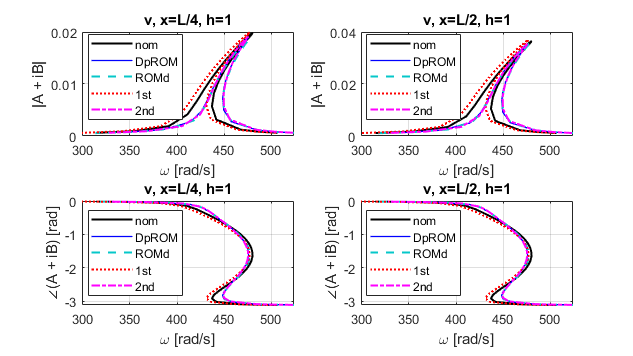

figure('units','normalized','position',[.2 .2 .6 .6])
plot_FRC(frc_data,items2plot,plotOptions);

#### Same plot, without nom and 1st order

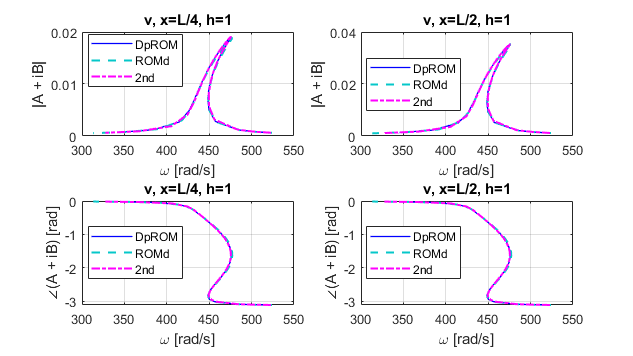

frc_data = {results.full.DpROM, results.full.ROMd, results.full.quad};
plotOptions.legend = {'DpROM','ROMd','2nd'};
plotOptions.color = {'b',[0.02,0.78,0.79],'m'};
plotOptions.lineWidth = {1.0, 1.5, 1.5};
plotOptions.lineStyle = {'-','--','-.'};
plotOptions.fontSize = 10;
plotOptions.marker = {'none','none','none'};
figure('units','normalized','position',[.25 .25 .6 .6])
plot_FRC(frc_data,items2plot,plotOptions);